%Initialization of parameters for MVDR estimation
clc;clear;
azimuth = [-10 20]/180*pi;
doa = azimuth;
N = 4500;           %No of sources 
f = 2*10^9;         %Freq=2 GHz
snr=5;              %SNR
w = 2*pi*f*[1 1]'; %Angular frequency
M = 10;             %Number of array elements
P = length(w);      %Number of signal
lambda = 150/1000;  %Wavelength
d = lambda/2;       %Element spacing
D = zeros(P,M);     %Creating a zero matrix with P rows and M columns

for k=1:P
  D(k,:) = exp(-1i*2*pi*d*sin(doa(k))/lambda*(0:M-1));
end
D=D';
%Generating Signals and Noise
Xs = 2*exp(1i*(w*(1:N))); %Generating the signal
X = D*Xs;
X = awgn(X,snr);          %Insert Gaussian White Noise
R = X*X';                 %Data Covariance Matrix

%Unmodified R applied MVDR and MUSIC calculations
[N,~] = eig(R);     %Find Eigenvalues and Eigenvectors of R
NN = N(:,1:M-P);    %Estimate Noise subspace

%Theta search for peak finding
theta = -90:0.5:90; %peak search
Pmusic = zeros(length(theta),1); %P music storing array
Pmvdr = zeros(length(theta),1);  %P mvdr storing array
Pconv = zeros(length(theta),1); %P conv storing array
for ii=1:length(theta)
    SS = zeros(1,length(M));
    for jj=0:M-1
        SS(1+jj) = exp(-1i*2*jj*pi*d*sin(theta(ii)/180*pi)/lambda);
    end
    PP = SS*(NN*NN')*SS';
    Pmusic(ii) = abs(1/PP);
    PQ = SS*(inv(R))*SS';
    Pmvdr(ii) = abs(1/PQ);
    Z = SS*R;
    Z=Z*SS';
    PC = (SS*SS')/abs(Z);
    Pconv(ii) = abs(1/PC);
end

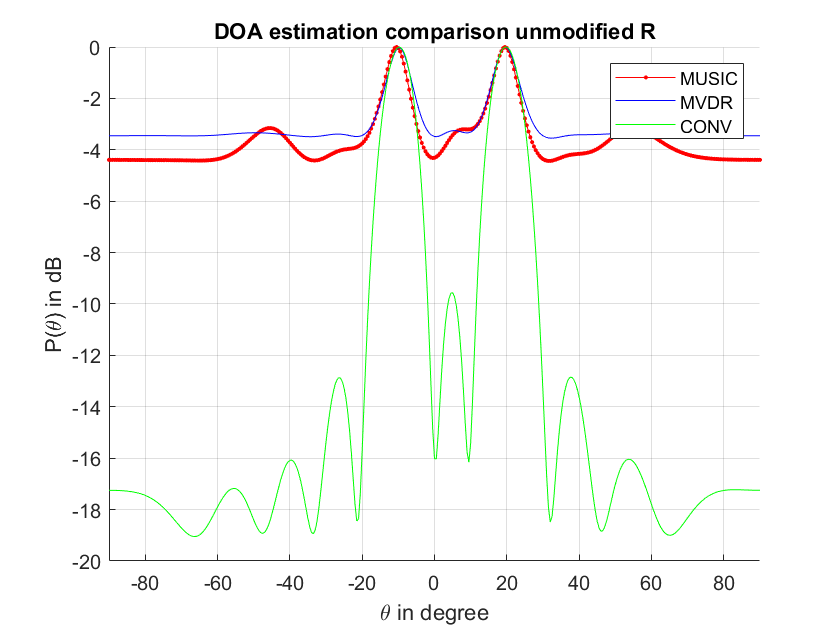

%Plotting the results of theta ,P music and P mvdr functions
%In the unmodified R case
%%Plotting the results of theta and Pmusic function
figure;
hold on
Pmusic = 10*log10(Pmusic/max(Pmusic));
plot(theta,Pmusic,'.-r');
Pmvdr = 10*log10(Pmvdr/max(Pmvdr));
plot(theta,Pmvdr,'-b')
Pconv = 10*log10(Pconv/max(Pconv));
plot(theta,Pconv,'-g');
xlabel('\theta in degree');
legend({'MUSIC','MVDR','CONV'});
ylabel('P({\theta}) in dB');
title('DOA estimation comparison unmodified R');
xlim([-90 90]);
grid on;

%MVDR and MUSIC estimations using modified R
%Unmodified R applied MVDR and MUSIC calculations
J=fliplr(eye(M));   %Anti Matrix
R = R+J*conj(R)*J;  %Modified R matrix
[N,~] = eig(R);     %Find Eigenvalues and Eigenvectors of R
NN = N(:,1:M-P);    %Estimate Noise subspace

%Theta search for peak finding
theta = -90:0.5:90; %peak search
Pmusic = zeros(length(theta),1); %P music storing array
Pmvdr = zeros(length(theta),1);  %P mvdr storing array
Pconv = zeros(length(theta),1); %P conv storing array
for ii=1:length(theta)
    SS = zeros(1,length(M));
    for jj=0:M-1
        SS(1+jj) = exp(-1i*2*jj*pi*d*sin(theta(ii)/180*pi)/lambda);
    end
    PP = SS*(NN*NN')*SS';
    Pmusic(ii) = abs(1/PP);
    PQ = SS*(inv(R))*SS';
    Pmvdr(ii) = abs(1/PQ);
    Z = SS*R;
    Z=Z*SS';
    PC = (SS*SS')/abs(Z);
    Pconv(ii) = abs(1/PC);
end

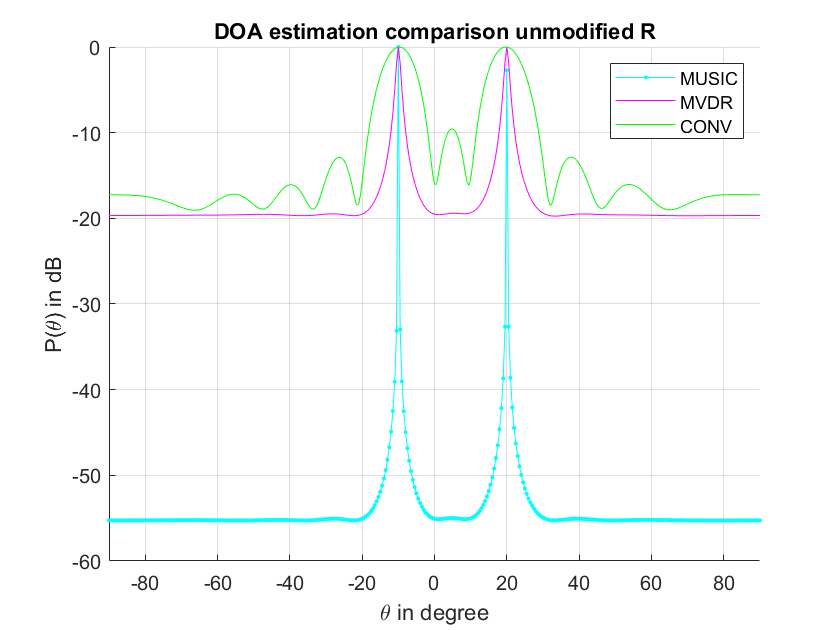

%Plotting the results of theta ,P music and P mvdr functions
%In the modified R case
%%Plotting the results of theta and Pmusic function
figure;
hold on
Pmusic = 10*log10(Pmusic/max(Pmusic));
plot(theta,Pmusic,'.-c');
Pmvdr = 10*log10(Pmvdr/max(Pmvdr));
plot(theta,Pmvdr,'-m')
Pconv = 10*log10(Pconv/max(Pconv));
plot(theta,Pconv,'-g');
xlabel('\theta in degree');
legend({'MUSIC','MVDR','CONV'});
ylabel('P({\theta}) in dB');
title('DOA estimation comparison modified R');
xlim([-90 90]);
grid on;